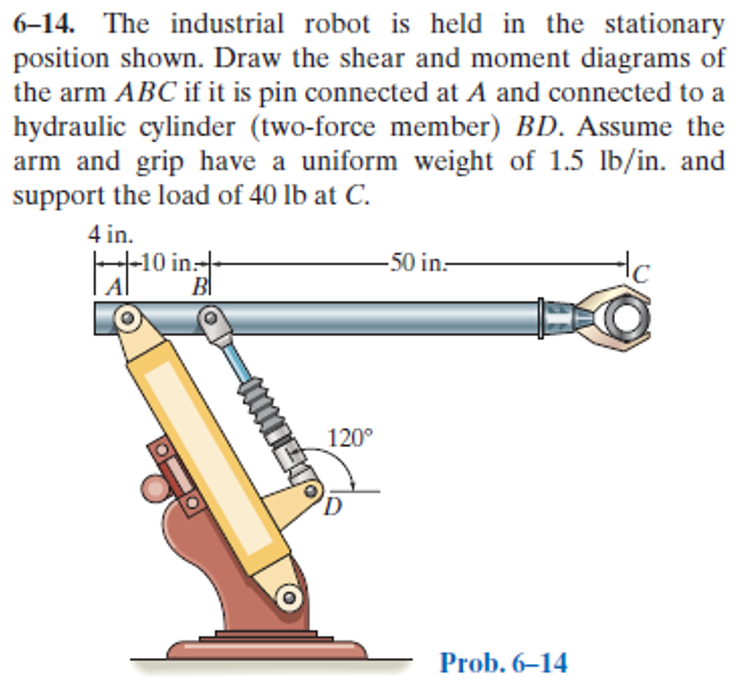

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-14P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-14P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

P = 40*u.lbf;
wo = 1.5*u.lbf/u.in;
L = 64*u.in;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 4*u.in);
b = b.add('reaction', 'force', 'Rb', 14*u.in);
b = b.add('concentrated', 'force', -P, L);
b = b.add('distributed', 'force', -wo, [0 L]);
b.L = L;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\left(x-4\,\mathrm{in}\right)\,\left(3\,x^{3}+12\,x^{2}\,\mathrm{in}+48\,x\,{\mathrm{in}}^{2}-309496\,{\mathrm{in}}^{3}\right)}{48\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\leq 4\,\mathrm{in}\\ -\frac{\left(x-4\,\mathrm{in}\right)\,\left(x-14\,\mathrm{in}\right)\,\left(15\,x^{2}+15182\,x\,\mathrm{in}+93492\,{\mathrm{in}}^{2}\right)}{240\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\in \left(4\,\mathrm{in},14\,\mathrm{in}\right]\\ -\frac{\left(x-14\,\mathrm{in}\right)\,\left(3\,x^{3}-1046\,x^{2}\,\mathrm{in}+120524\,x\,{\mathrm{in}}^{2}-872592\,{\mathrm{in}}^{3}\right)}{48\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }14\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{77422\,{\mathrm{in}}^{3}-3\,x^{3}}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\leq 4\,\mathrm{in}\\ \frac{-15\,x^{3}-11184\,x^{2}\,\mathrm{in}+89472\,x\,{\mathrm{in}}^{2}+208166\,{\mathrm{in}}^{3}}{60\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\in \left(4\,\mathrm{in},14\,\mathrm{in}\right]\\ -\frac{3\,x^{3}-816\,x^{2}\,\mathrm{in}+67584\,x\,{\mathrm{in}}^{2}-639982\,{\mathrm{in}}^{3}}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }14\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{3\,x^{2}}{4}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\leq 4\,\mathrm{in}\\ -\frac{15\,x^{2}+7456\,x\,\mathrm{in}-29824\,{\mathrm{in}}^{2}}{20}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\in \left(4\,\mathrm{in},14\,\mathrm{in}\right]\\ -\frac{\left(x-64\,\mathrm{in}\right)\,\left(3\,x-352\,\mathrm{in}\right)}{4}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }14\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{3\,x}{2}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\leq 4\,\mathrm{in}\\ -\frac{15\,x+3728\,\mathrm{in}}{10}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\in \left(4\,\mathrm{in},14\,\mathrm{in}\right]\\ -\frac{3\,x-272\,\mathrm{in}}{2}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }14\,\mathrm{in}<x \end{array}\right.$$

w

$$w(x) = -\frac{3}{2}\,\frac{\mathrm{lbf}}{\mathrm{in}}$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & -372.8\,\mathrm{lbf}\\ \mathrm{Rb} & 508.8\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

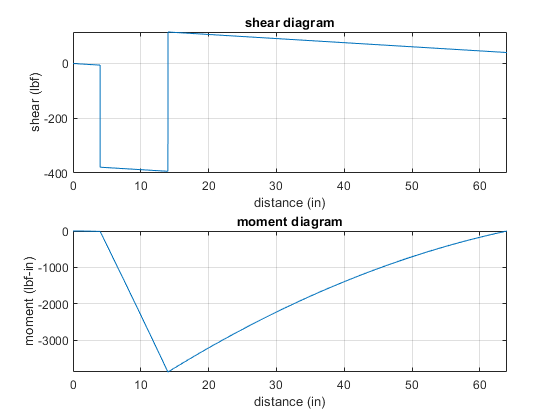

beam.shear_moment(m, v, [0 b.L], {'lbf' 'in'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa ha_vpa;